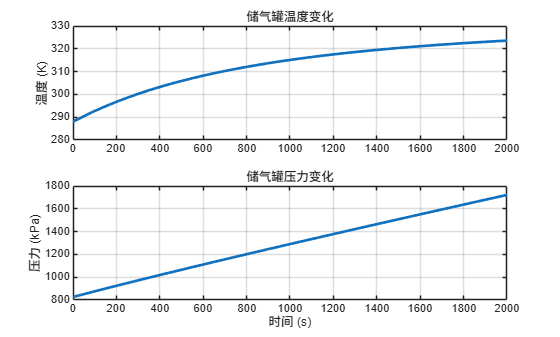

%% 使用示例：用户输入所有参数

Tin  = 373;        % 入口气体温度 (K)
mdot = 0.427;      % 质量流量 (kg/s)
R    = 0.287;      % 空气气体常数 (kJ/kg*K)

V    = 100;        % 储气罐体积 (m^3)
A    = 30;         % 换热面积 (m^2)
h    = 0.0135;     % 换热系数
Tamb = 288;        % 环境温度 (K)

T0 = 288;          % 初始温度
m0 = 1000;          % 初始质量
t_end = 2000;      % 仿真时间

% 调用函数
result = Gas_storage_tank_input(Tin, mdot, R, V, A, h, Tamb, T0, m0, t_end);

% 绘图
figure;
subplot(2,1,1)
plot(result.time, result.T, 'LineWidth', 2); grid on
ylabel('温度 (K)')
title('储气罐温度变化')

subplot(2,1,2)
plot(result.time, result.P, 'LineWidth', 2); grid on
xlabel('时间 (s)')
ylabel('压力 (kPa)')
title('储气罐压力变化')